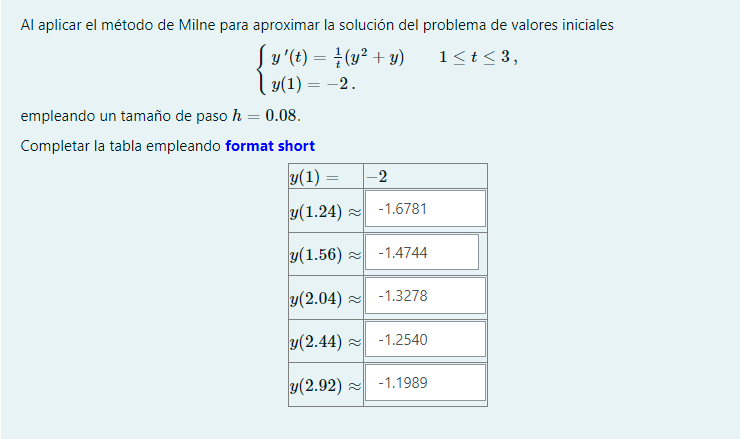

f = @(t,y) 1/t*(y^2+y)

f = function_handle with value:
    @(t,y)1/t*(y^2+y)


a=1;b=3; ya=-2; h=0.08; M = (b-a)/h; 
ML = Milne(f,a,b,ya,M)

ML =     1.0000   -2.0000
    1.0800   -1.8637
    1.1600   -1.7598
    1.2400   -1.6781
    1.3200   -1.6092
    1.4000   -1.5572
    1.4800   -1.5110
    1.5600   -1.4744
    1.6400   -1.4370
    1.7200   -1.4120


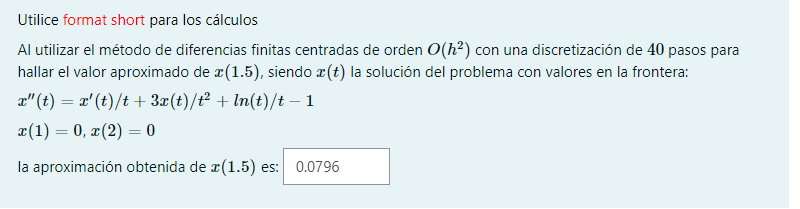

p = @(t) 1./t; % Valor que acompaña a Y
q = @(t) 3./(t.^2) % Valor que acompaña Y'

q = function_handle with value:
    @(t)3./(t.^2)


r = @(t) log(t)./(t)-1 % Termino independiente 

r = function_handle with value:
    @(t)log(t)./(t)-1


N=40;
a=1; b=2;
alpha = 0;
beta = 0;
F = findiff (p, q, r, a, b, alpha, beta, N)

F =     1.0000         0
    1.0250    0.0076
    1.0500    0.0148
    1.0750    0.0216
    1.1000    0.0280
    1.1250    0.0340
    1.1500    0.0396
    1.1750    0.0448
    1.2000    0.0497
    1.2250    0.0542


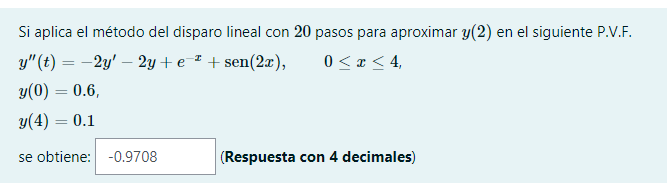

F1 = @(t,U) [U(2), -2*U(2)-2*U(1)+exp(-t)+sin(2*t)]
F2 = @(t,U) [U(2), -2*U(2)-2*U(1)]
a=0; b=4; 
alpha = 0.6;

F1 = function_handle with value:
    @(t,U)[U(2),-2*U(2)-2*U(1)+exp(-t)+sin(2*t)]


beta = 0.1;

F2 = function_handle with value:
    @(t,U)[U(2),-2*U(2)-2*U(1)]


M=20;
L = linsht (F1, F2, a, b, alpha, beta, M) % Metodo del disparo

% Melo. Kelly, me debe unas gomitas

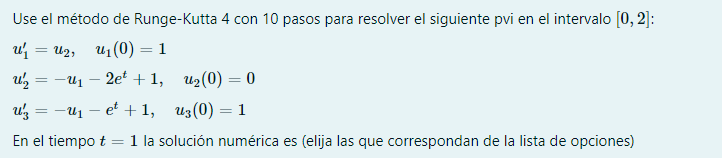

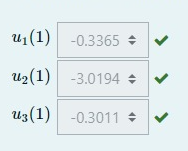

% Entrada   - F funcion vectorial creada con @

L =          0    0.6000
    0.2000   -1.3151
    0.4000   -2.4730
    0.6000   -3.0417
    0.8000   -3.1755
    1.0000   -3.0102
    1.2000   -2.6610
    1.4000   -2.2213
    1.6000   -1.7626
    1.8000   -1.3353


%           - a y b los extremos del intervalo
%           - Za = [x1(a), ... , xn(a)] las condiciones iniciales

F1 = function_handle with value:
    @(t,U)[U(2),-2*U(2)-2*U(1)+exp(-t)+sin(2*t)]


F2 = function_handle with value:
    @(t,U)[U(2),-2*U(2)-2*U(1)]


L =          0    0.6000
    0.2000   -1.3151
    0.4000   -2.4730
    0.6000   -3.0417
    0.8000   -3.1755
    1.0000   -3.0102
    1.2000   -2.6610
    1.4000   -2.2213
    1.6000   -1.7626
    1.8000   -1.3353


%           - M es el numero de pasos (el h)
% Salida    - T es el vector de pasos
%           - Z = [x1(t), ... , xn(t)] donde  xk(t)  es la aproximacion a la
%             k-esima variable dependiente


a=0; b=2; M = 10; Za= [1 0 1]

F = function_handle with value:
    @(t,U)[U(2),-U(1)-2*exp(t)+1,-U(1)-exp(t)+1]


% falta definir a F vectorialmente
F = @(t,U) [U(2), -U(1)-2*exp(t)+1, -U(1)-exp(t)+1]

Za =      1     0     1



[T, Z] = rks4 (F, a, b, Za, M) % Aqui estan las soluciones, pero hay que 

F = function_handle with value:
    @(t,U)[U(2),-U(1)-2*exp(t)+1,-U(1)-exp(t)+1]


% Organizar para que se vea bonito

[T',Z] % Se mira la fila de 1, salen U1 ; U2 ; U3 en las columnas2,3,4

T =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000


Z =     1.0000         0    1.0000
    0.9573   -0.4400    0.7814
    0.8186   -0.9602    0.5317
    0.5679   -1.5614    0.2607
    0.1885   -2.2462   -0.0206
   -0.3365   -3.0194   -0.3011
   -1.0257   -3.8897   -0.5696
   -1.8998   -4.8706   -0.8154
   -2.9826   -5.9817   -1.0287
   -4.3030   -7.2506   -1.2009


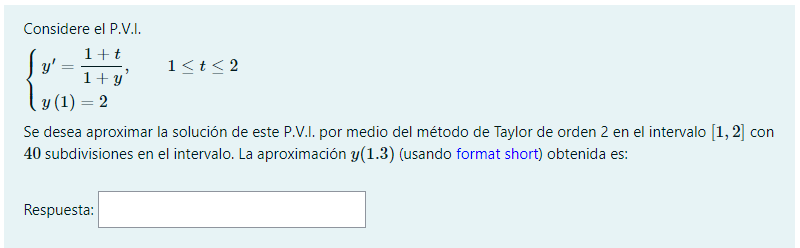

a=1; b=2; M=40; n=2;ya=2;

ans =          0    1.0000         0    1.0000
    0.2000    0.9573   -0.4400    0.7814
    0.4000    0.8186   -0.9602    0.5317
    0.6000    0.5679   -1.5614    0.2607
    0.8000    0.1885   -2.2462   -0.0206
    1.0000   -0.3365   -3.0194   -0.3011
    1.2000   -1.0257   -3.8897   -0.5696
    1.4000   -1.8998   -4.8706   -0.8154
    1.6000   -2.9826   -5.9817   -1.0287
    1.8000   -4.3030   -7.2506   -1.2009


F = function_handle with value:
    @(t,U)[U(2),-U(1)-2*exp(t)+1,-U(1)-exp(t)+1]


M = 10

ans =          0    1.0000         0    1.0000
    0.2000    0.9573   -0.4400    0.7814
    0.4000    0.8186   -0.9602    0.5317
    0.6000    0.5679   -1.5614    0.2607
    0.8000    0.1885   -2.2462   -0.0206
    1.0000   -0.3365   -3.0194   -0.3011
    1.2000   -1.0257   -3.8897   -0.5696
    1.4000   -1.8998   -4.8706   -0.8154
    1.6000   -2.9826   -5.9817   -1.0287
    1.8000   -4.3030   -7.2506   -1.2009



syms t y

f = (1+t)/(1+y)

T = taylorN(f,n, a, b, ya, M) % Rta es 2.2080 MELISIMO

$$f = \frac{t+1}{y+1}$$

T =     1.0000    2.0000
    1.0250    2.0167
    1.0500    2.0336
    1.0750    2.0505
    1.1000    2.0676
    1.1250    2.0847
    1.1500    2.1020
    1.1750    2.1194
    1.2000    2.1369
    1.2250    2.1545
